Santeri Saariokari 253345

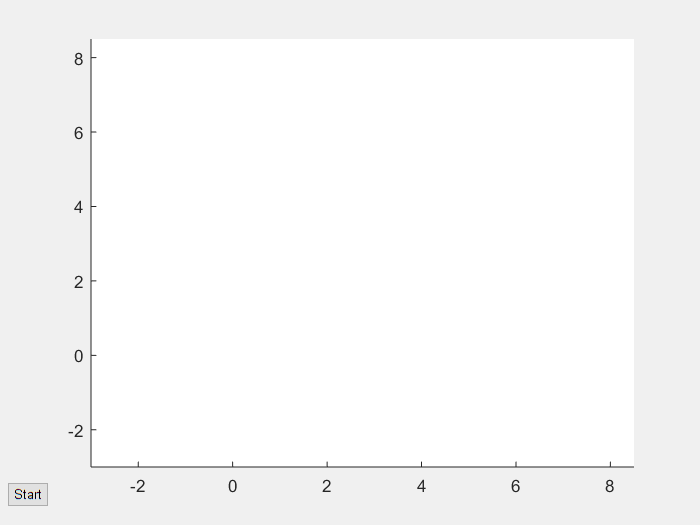

clf
axis([-3 8.5 -3 8.5])
uicontrol('Style', 'pushbutton', 'Units', 'char', 'Position', [1 1 6 1.5],...
    'UserData', false, 'String', 'Start', 'Callback', @startbuttonCallback)

function startbuttonCallback(hObject, ~) % Don't need the second argument
% A callback for the Start/Stop button.

if hObject.UserData
    % Animation is currently running. Setting UserData to false stops it.
    hObject.UserData = false;
else
    % Animation is not running, so we start it and change the button text to
    % 'Stop'.
    hObject.UserData = true;
    hObject.String = 'Stop';
    
    cla % Clear the axes
    
    % Create an animatedline object with initial point (4, 1.9) and
    % set h to a handle to it.
    xo = 4; yo = 1.9;
    h = animatedline(xo, yo, 'LineStyle', 'none', 'Marker', '.',...
        'MarkerSize', 1, 'MaximumNumPoints', Inf, 'Color', [0.65, 0.45, 0.25]);

    % The animation loop continues until UserData becomes false when the user
    % clicks the button.
    % We add new points to the plot with the function addpoints.
    while hObject.UserData
        x = 1 - yo + abs(xo);
        y = xo;
        addpoints(h, x, y);
        drawnow
        xo = x; yo = y;
    end
    hObject.String = 'Start'; % Restore the button text to 'Start'
end
end